b = 0.1;
g = 9.81;

%{
structure v1, short
% very small structure
%kp = 0.5, ki = 0.5, kd = 0.05

M_wheel_alone = 0.04;
M_motor= 0.04;
M_wheel = M_wheel_alone;
M_body=0.2010;

r = 0.062;
l = 0.05;
%}


%{
structure v2, short, heavy motors
M_wheel = 0.02;
M_Motor = 0.180;
M_body_mass = 0.3;
M_body = M_body_mass + 2*M_Motor
r_motor = 0.015
r = 0.1;
l = 0.08
%kp = 0.5, ki = 0.5, kd = 0.05
%}


% structure v1, short, calibrated for servos
M_wheel_alone = 0.012;
M_motor= 0.011;
M_wheel = M_wheel_alone;
M_body=0.232;

r_motor = 0.015;
r = 0.032;
l = 0.035;

dt = 0.001;

% kp = 0.3, ki = 0.2, kd = 0.05

% inertia
I_wheel = (M_wheel*r^2); %placeholder
I_body = M_body*l^2/3; %placeholder

% initial conditions of yaw
initial_angle = 0;
initial_angle_rad = initial_angle/180*pi

initial_angle_rad = 0


% saturation of motor torque, in Nm
sat = 0.7;
res = sim('self_balance_pid_discr_torquereverse_pidzn2.slx');

Found algebraic loop containing: 
self_balance_pid_discr_torquereverse_pidzn2/Subsystem/Gain2
self_balance_pid_discr_torquereverse_pidzn2/Subsystem/Gain4
self_balance_pid_discr_torquereverse_pidzn2/Subsystem/Add
self_balance_pid_discr_torquereverse_pidzn2/Subsystem/Gain
self_balance_pid_discr_torquereverse_pidzn2/Subsystem/Gain6


%res = sim('self_balance_nonlinear.slx')

% plot(results.plot)

obsv_kp = 10;
obsv_pc = 0.083;
ti = 0.5*obsv_pc;
td = 0.125*obsv_pc;
ki = obsv_kp * dt / ti

ki = 0.2410

kd = obsv_kp * td / dt

kd = 103.7500

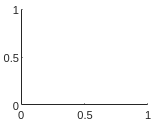


hold on